功能说明：Kalman滤波用于自由落体运动目标跟踪问题

delta_t：采样间隔时间 （秒）

N：采样个数

delta_t = 0.01;
N       = 21 / delta_t ;

噪声，方差决定噪声的大小

Q：过程噪声的方差，忽略空气阻力时为0

R：观测噪声方差

W：过程噪声

Q：观测噪声

Q       = [0 0; 0 0];
R       = 10;
W       = sqrt(Q) * randn(2, N);
V       = sqrt(R) * randn(1, N);

系统矩阵，本系统状态为二维

A：状态转移矩阵

B：控制矩阵

U：控制量，重力加速度，取9.8m/s/s

H：观测矩阵

A       = [1 -delta_t; 0 1];
B       = [-0.5 * delta_t^2; 1];
U       = 9.8 * delta_t;
H       = [1 0];

初始化

X：物体真实状态

X(:, 1)：初始位置和速率

P：方差

Z：观测值

Z(1)：初始观测值

Xkf：Kalman估计值

err_P：误差均方值

I：二维系统

pass_time：经过的时间（秒）

X          = zeros(2, N);
X(:, 1)    = [2000; 10];
P          = [100 0; 0 2];
Z          = zeros(1, N);
Z(1)       = H*X(:, 1);
Xkf        = zeros(2, N);
Xkf(:, 1)  = X(:, 1);
err_P      = zeros(N, 2);
err_P(1,1) = P(1, 1);
err_P(1,2) = P(2, 2);
I          = eye(2);
pass_time  = zeros(1, N);

模拟自由落体过程，并滤波

pass_time(1) = 0;
for k = 2: N
    pass_time(k) = pass_time(k-1) + delta_t;

第一步：物体下落，受状态方程的驱动

    X(:, k) = A * X(:, k-1) + B * U + W(k-1);

第二步：位置观测

    Z(k) = H * X(:, k) + V(k);

第三步：Kalman滤波

X_pre：状态预测

P_pre：协方差预测

Kg：Kalman增益

Xkf(:, k)：状态更新

P：协方差更新

    X_pre     = A * Xkf(:, k-1) + B * U;
    P_pre     = A*P*A' + Q;
    Kg        = P_pre * H' * inv(H*P_pre*H' + R);
    Xkf(:, k) = X_pre + Kg * (Z(k) - H * X_pre);
    P         = (I-Kg*H) * P_pre;
    
    err_P(k, 1) = P(1, 1);
    err_P(k, 2) = P(2, 2);
end

计算误差

messure_err_x：位移的测量误差

kalman_err_x：Kalman估计的位移与真实位移之间的偏差

kalman_err_v：Kalman估计的速度与真实速度之间的偏差

messure_err_x = zeros(1, N);
kalman_err_x  = zeros(1, N);
kalman_err_v  = zeros(1, N);
for k = 1: N
    messure_err_x(k) = Z(k) - X(1, k);
    kalman_err_x(k)  = Xkf(1, k) - X(1, k);
    kalman_err_v(k)  = Xkf(2, k) - X(2, k);
end

画图显示

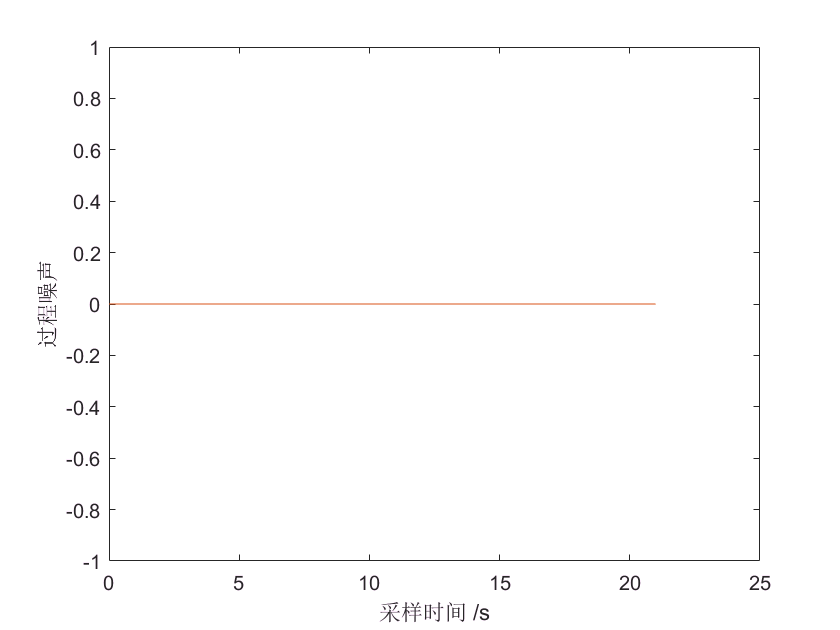

figure
plot(pass_time, W);
xlabel('采样时间 /s');
ylabel('过程噪声');

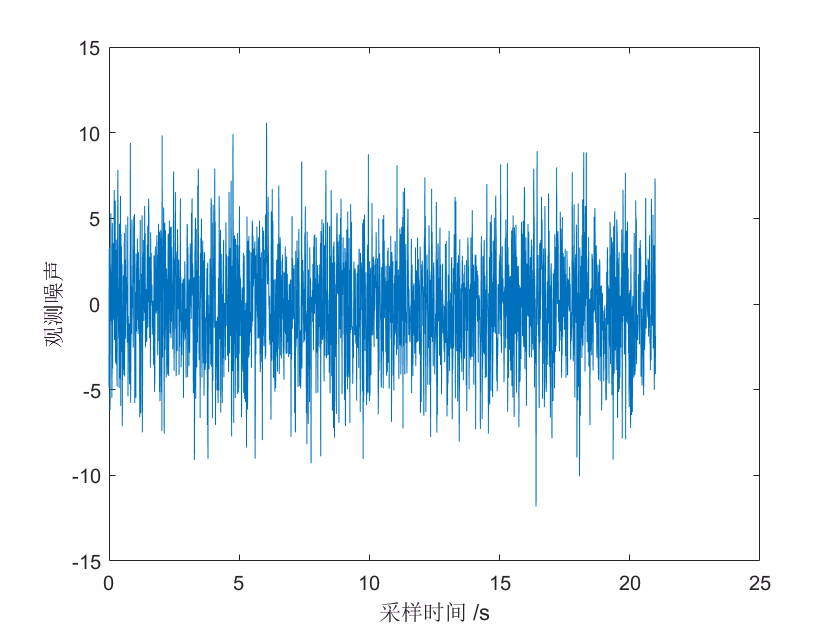

figure
plot(pass_time, V);
xlabel('采样时间 /s');
ylabel('观测噪声');

位置偏差

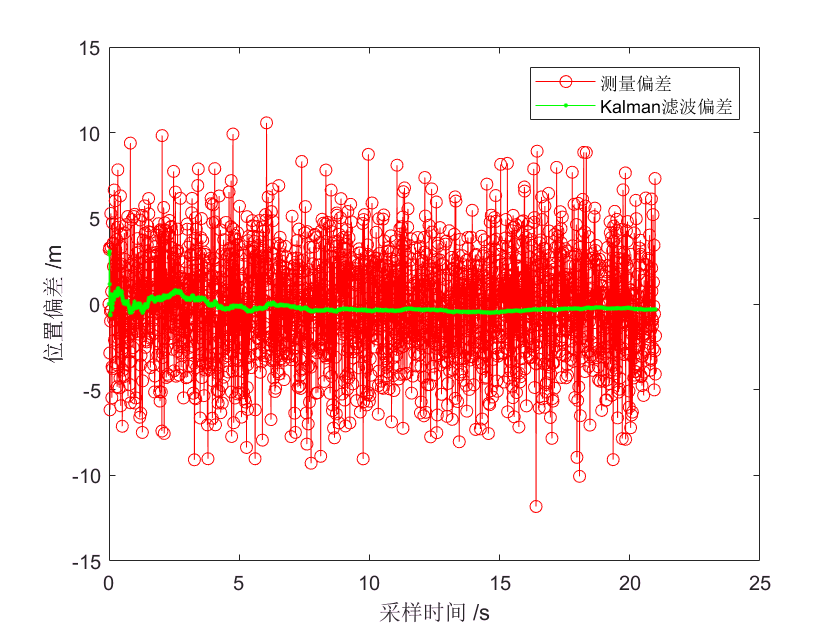

figure
hold on, box on;
plot(pass_time, messure_err_x, '-ro');
plot(pass_time, kalman_err_x , '-g.');
legend('测量偏差', 'Kalman滤波偏差');
xlabel('采样时间 /s');
ylabel('位置偏差 /m');

Kalman速度偏差

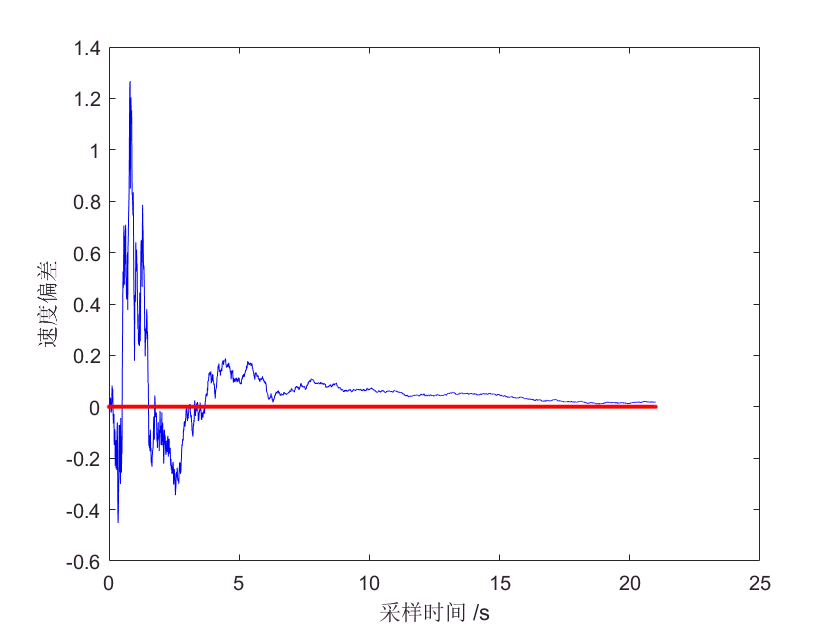

figure
plot(pass_time, kalman_err_v, 'b', pass_time, 0, 'r.');
xlabel('采样时间 /s');
ylabel('速度偏差');

均方值

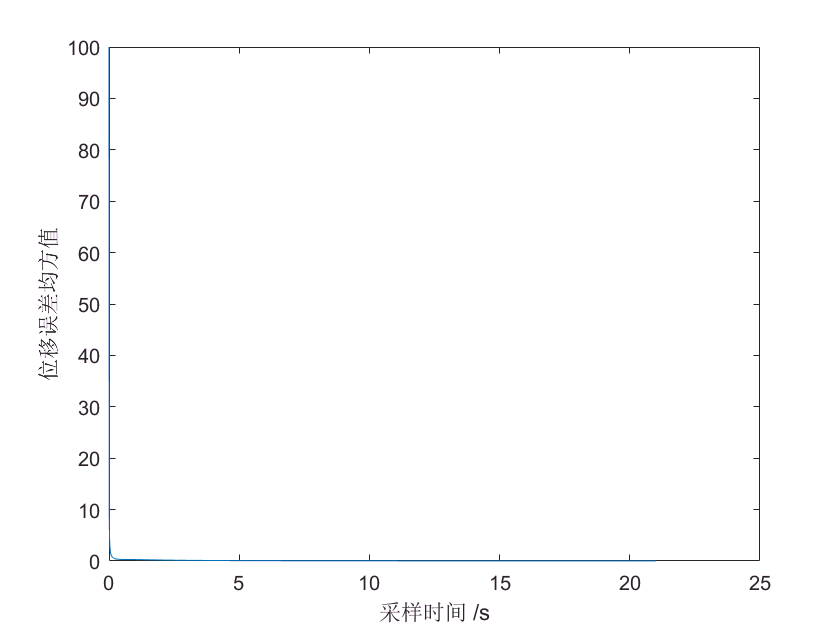

figure
plot(pass_time, err_P(:, 1));
xlabel('采样时间 /s');
ylabel('位移误差均方值');

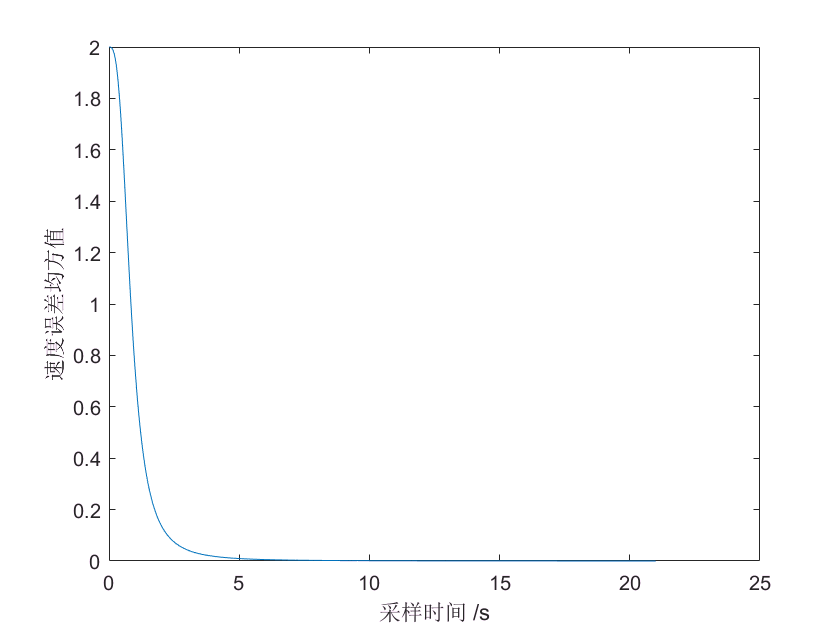

figure
plot(pass_time, err_P(:, 2));
xlabel('采样时间 /s');
ylabel('速度误差均方值');

真实位置、观测位置和Kalman滤波后的位置

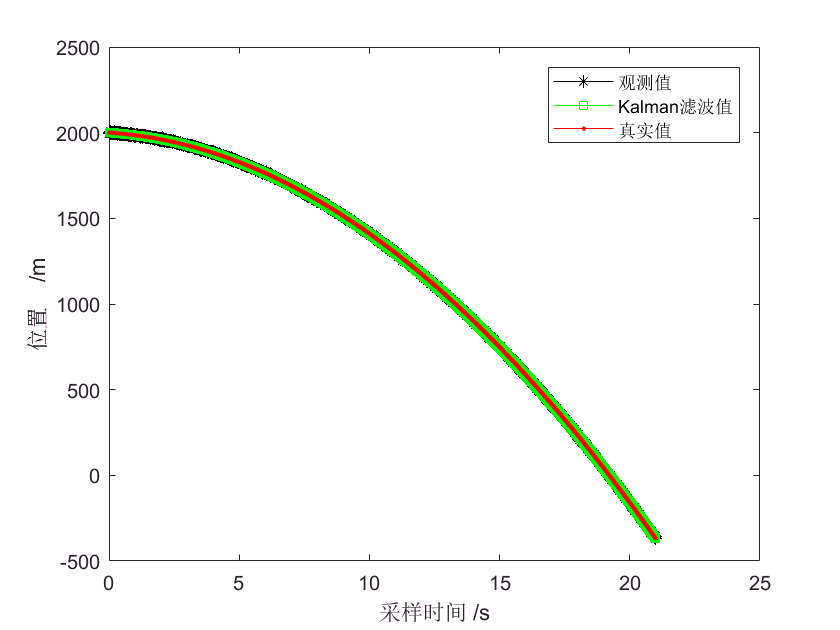

figure
plot(pass_time, Z, '-k*', pass_time, Xkf(1, :), '-gs', pass_time, X(1, :), '-r.');
legend('观测值', 'Kalman滤波值', '真实值');
xlabel('采样时间 /s');
ylabel('位置    /m');

真实速度和Kalman滤波后的速度

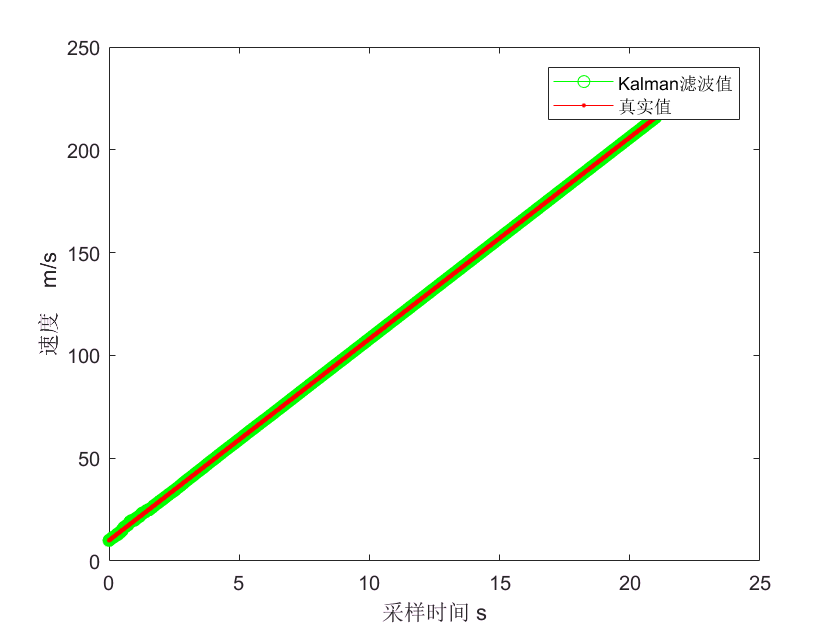

figure
plot(pass_time, Xkf(2, :), '-go', pass_time, X(2, :), '-r.');
legend('Kalman滤波值', '真实值');
xlabel('采样时间 s');
ylabel('速度    m/s');